% Preprocess Color Using a Datastore

% Instructions are in the task pane to the left. Complete and submit each task one at a time.
% 
% This code displays the images in the current folder and imports AlexNet.
ls *.jpg


test01.jpg  test02.jpg  test03.jpg  



net = alexnet

net =   SeriesNetwork - 属性:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


% This code creates an image datastore of these images.
imds = imageDatastore('test*.jpg')

imds =   ImageDatastore - 属性:

                       Files: {
                              'E:\MATLAB_Workspace\CNN\test01.jpg';
                              'E:\MATLAB_Workspace\CNN\test02.jpg';
                              'E:\MATLAB_Workspace\CNN\test03.jpg'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


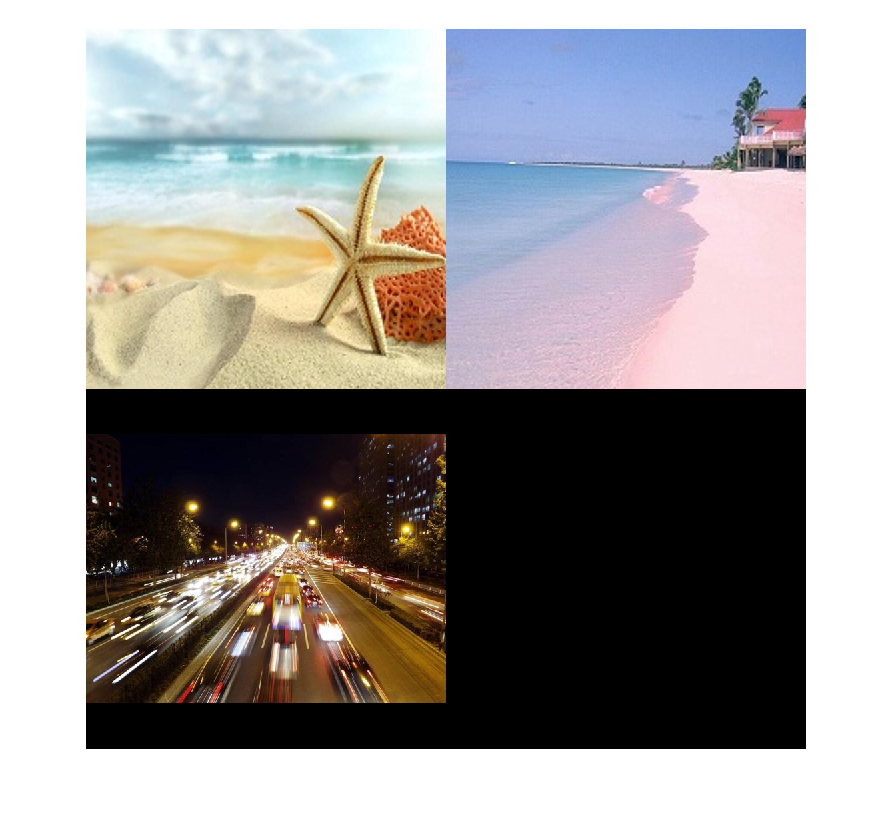


% Task 1
% Display images in imds
montage(imds)


% Task 2
% Create augmentedImageDatastore
auds = augmentedImageDatastore([227 227], imds,'ColorPreprocessing','gray2rgb')

auds =   augmentedImageDatastore - 属性:

             NumObservations: 3
                       Files: {3×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0



% Task 3
% Classify datastore
preds = classify(net,auds)

preds = 3×1 categorical 数组
     conch 
     sandbar 
     fountain 
